# piDMD w/ dimensional reduction via LSUN for Conservative systems

References

- Baddoo Peter J., Herrmann Benjamin, McKeon Beverley J., Nathan Kutz J. and Brunton Steven L. 2023Physics-informed dynamic mode decompositionProc. R. Soc. A.4792022057620220576, [http://doi.org/10.1098/rspa.2022.0576](http://doi.org/10.1098/rspa.2022.0576)

- Brunton, S. L., & Kutz, J. N. (2022). *Data-Driven Science and Engineering: Machine Learning, Dynamical Systems, and Control* (2nd ed.). Cambridge: Cambridge University Press.

- Kutz JN, Brunton SL, Brunton BW, Proctor JL. 2016 *Dynamic mode decomposition: data-driven modeling of complex systems*. Philadelphia, PA: SIAM.

clear 
close all

## Parameter Setup

nModes4PODtrunc = 15; 
nCoefs4LSUNtrunc = 2;  
nrows = 199;
ncols = 449;

## Source Data Preparation

load("../../../data/databook_DATA/DATA/VORTALL");
ut = reshape(VORTALL,nrows,ncols,[]);

## Source Data Visualization

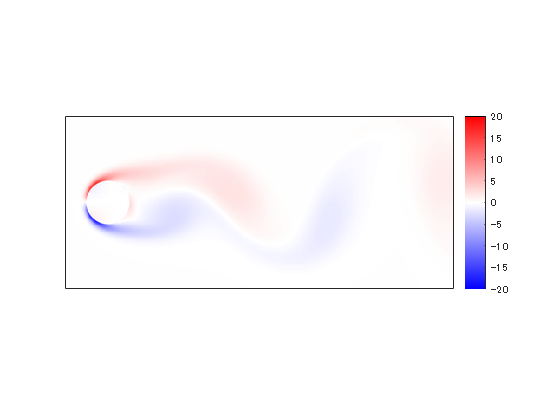

clims = 1.1*[min(ut,[],'all') max(ut,[],'all')];
nFrames = size(ut,3);
him = [];
for iFrame = 1:nFrames
    x = ut(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
    end
    drawnow
end

% exportgraphics

% POD truncation
Xorg = reshape(ut,[],size(ut,3));
Xo = Xorg(:,1:end-1);
%Yo = Xorg(:,2:end);
[Psiorg,Sorg,Vorg] = svds(Xo,nModes4PODtrunc);
Atorg = Sorg*Vorg';

% Approximation
Xtilde = Psiorg*Atorg;
mean((Xo-Xtilde).^2,'all')

ans = 3.2466e-05

## Noisy Data Preparation

Noise energy set to 20% of signal energy

varu = var(ut,0,'all');
varw = 0.2*varu; 
sigmaw = sqrt(varw);
vt = ut + sigmaw * randn(size(ut),'like',ut);

## Noisy Data Visualization

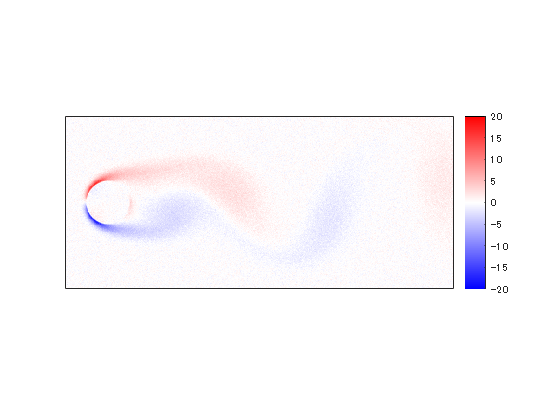

him = [];
for iFrame = 1:nFrames
    x = vt(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
    end
    drawnow
end

% exportgraphics

## Experiments

### Define data matrix

Xnoisy = reshape(vt,[],size(vt,3));
Xn = Xnoisy(:,1:end-1);
Yn = Xnoisy(:,2:end);

## exact DMD w/ leading POD truncation

[exA, exVals] = piDMD(Xn,Yn,'exact',nModes4PODtrunc); % Original exact DMD

## piDMD w/ leading POD mode truncation

- Apply POD

- Project data onto the leading POD modes

- Apply piDMD

### piDMD w/ inside POD truncation (for validation)

[piA0, piVals0] = piDMD(Xn,Yn,'orthogonal',nModes4PODtrunc); % Original piDMD

### piDMD w/ outside POD truncation

% Project X and Y onto principal components
[Psi,~,~] = svds(Xn,nModes4PODtrunc);
Xproj= Psi'*Xn; Yproj = Psi'*Yn; 
[piA1, piVals1] = piDMD(Xproj,Yproj,'orthogonal'); 
piApod = @(x) Psi*piA1(Psi'*x);

% Assesment 
assert(mean((piVals0-piVals1).*conj(piVals0-piVals1))<1e-9)
assert(mean((piApod(Xn)-piA0(Xn)).^2,'all')<1e-9)

## piDMD w/ dimensional reduction via LSUN

- Train LSUN 

- Project data onto the LSUN feature space

- Apply piDMD

### Train LSUN

% Decimation factor (Strides)
blksz = 4.*[1 1]; % Block size
stride = blksz; % [My Mx]
% Number of overlapping blocks (Polyphase order plus one)
nof = 2;
ky = 2*nof+1; % # of overlapping blocks (odd number)
kx = 2*nof+1;
ovlpFactor = [ky kx];
% # of coeffs
nCoefs = 1;
% Max epochs
maxEpochs = 8;
% Mini batch size
miniBatchSize = 5;
% Standard deviation of initial angles
stdInitAng = 1e-6;
% No DC-leakage
noDcLeakage = false;
strbuf = "";
strbuf = strbuf.append(sprintf('---- LSUN Parametars -----------------------     \n'));
strbuf = strbuf.append(sprintf('Block size                           [%d %d]  \n',blksz));
strbuf = strbuf.append(sprintf('Strides                              [%d %d]  \n',stride));
strbuf = strbuf.append(sprintf('Overlapping blocks                   [%d %d]  \n',ky,kx));
strbuf = strbuf.append(sprintf('nCoef                                [%d]     \n',nCoefs));
strbuf = strbuf.append(sprintf('Max epochs                           [%d]     \n',maxEpochs));
strbuf = strbuf.append(sprintf('Mini batch size                      [%d]     \n',miniBatchSize));
strbuf = strbuf.append(sprintf('Standard deviation of initial angles [%d]     \n',stdInitAng));
strbuf = strbuf.append(sprintf('No DC-leakage                        [%d]     \n',noDcLeakage));
strbuf = strbuf.append(sprintf('--------------------------------------------     \n'));
disp(strbuf)

---- LSUN Parametars -----------------------     
Block size                           [4 4]  
Strides                              [4 4]  
Overlapping blocks                   [5 5]  
nCoef                                [1]     
Max epochs                           [8]     
Mini batch size                      [5]     
Standard deviation of initial angles [1.000000e-06]     
No DC-leakage                        [0]     
--------------------------------------------     



### Pad array

szy = ceil(nrows/blksz(1))*blksz(1);
szx = ceil(ncols/blksz(2))*blksz(2);
% Pad zeros to make the size multiples of nDecs.
vtpad = padarray(vt,[szy szx]-[nrows ncols],0,'post');

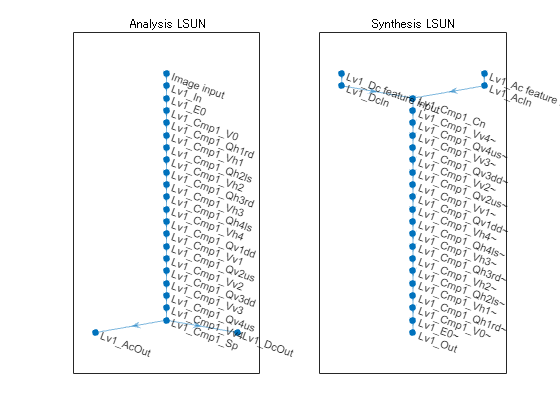

import tansacnet.lsun.*
analysislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
synthesislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis LSUN')

### Construction of synthesis/analysis network

% Construction of synthesis network.
analysisnet = dlnetwork(analysislgraph);

% Initialize
nLearnables = height(analysisnet.Learnables);
for iLearnable = 1:nLearnables
    if analysisnet.Learnables.Parameter(iLearnable)=="Angles"
        analysisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end
    
import tansacnet.lsun.*
% Construction of analysis network
analysislgraph = layerGraph(analysisnet);
synthesislgraph = fcn_cpparamsana2syn(synthesislgraph,analysislgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vh3 to Lv1_Cmp1_Vh3~
Copy angles from Lv1_Cmp1_Vh4 to Lv1_Cmp1_Vh4~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~
Copy angles from Lv1_Cmp1_Vv3 to Lv1_Cmp1_Vv3~
Copy angles from Lv1_Cmp1_Vv4 to Lv1_Cmp1_Vv4~


synthesisnet = dlnetwork(synthesislgraph);

### Confirmation of the adjoint relation (perfect reconstruction)

x = rand([szy szx],'double');
dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 1.7599e-09"



## Parameter optimization and approximation

### Create analysis layerGraph

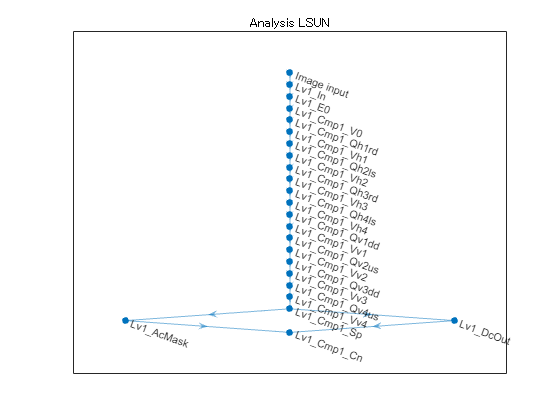

import tansacnet.lsun.*
analysislgraph = layerGraph(analysisnet);

% Coefficient masking
nChsTotal = prod(stride);
coefMask = [ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)];
coefMask = [coefMask(1:2:end); coefMask(2:2:end)];
%nLevels = 1;
%for iLv = nLevels:-1:1
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
analysislgraph = analysislgraph.replaceLayer([strLv 'AcOut'],...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
%strLvPre = strLv;
%end

% Output layer
iCmp = 1;
strCmp = sprintf('Cmp%0d_',iCmp);
%analysislgraph = analysislgraph.addLayers([...
%      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']) ...
%      lsunRegressionLayer('Coefficient output')
%     ]);
analysislgraph = analysislgraph.addLayers(...
      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']));
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'AcMask' ], [strLv strCmp 'Cn/ac']);
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'DcOut' ], [strLv strCmp 'Cn/dc']);

figure
plot(analysislgraph)
title('Analysis LSUN')

### Training Data Set

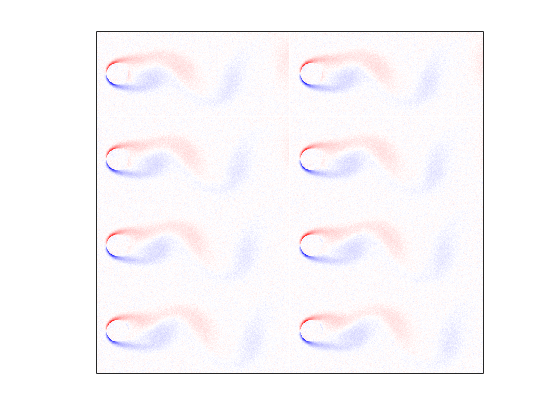

% Image data store
arrds = arrayDatastore(vtpad(:,:,1:end-1),'IterationDimension',3);
figure
dataOut = preview(arrds);
tile = imtile(dataOut);
mycylinderplot_([],tile,clims);

drawnow

## Training

numimgs = nFrames-1;
mbq = minibatchqueue(arrds,...
    'MiniBatchSize',miniBatchSize,...
    'OutputAsDlarray',1,...
    'MiniBatchFcn',@preprocessMiniBatch,...
    'MiniBatchFormat','SSCB',...
    'OutputCast','double',...
    'OutputEnvironment','gpu');
shuffle(mbq)
dlX = next(mbq);
trainnet = dlnetwork(analysislgraph,dlX);
trainnet.Initialized   

ans = logical
   1


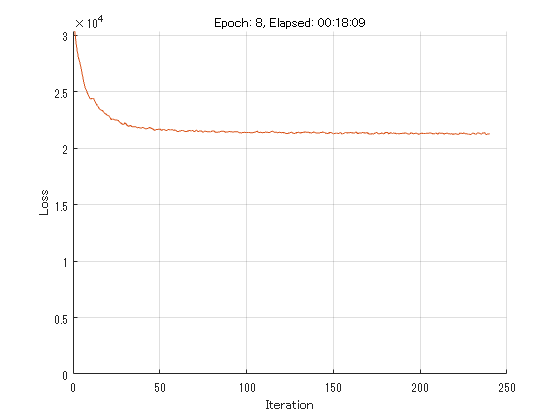

% Configuration
figure
lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

velocity = [];
iteration = 0.01;
momentum = 0.9;
decay = 0.01;
initialLearnRate = 1e-4;

% Loop over epochs.
start = tic;
for epoch = 1:maxEpochs

    % Shuffle data.
    shuffle(mbq)

    while hasdata(mbq)
        % Loop over mini-batches.
        iteration = iteration + 1;
    
        % Read mini-batch of data.
        dlX = next(mbq);

        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [gradients,loss] = dlfeval(@modelGradients,trainnet,dlX);
        
        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + decay*iteration);

        % Update the network parameters using the SGDM optimizer.
        [trainnet,velocity] = sgdmupdate(trainnet,gradients,velocity,learnRate,momentum);

        % Display the training progress.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        addpoints(lineLossTrain,iteration,loss)
        title("Epoch: " + epoch + ", Elapsed: " + string(D))
        drawnow
    end
end

lsunresfile = "../../../results/lsun4pidmd"+string(datetime('now','TimeZone','local','Format','yyyy-M-dd-HH-mm-ssZ'))

lsunresfile = "../../../results/lsun4pidmd2024-3-13-10-09-09+0900"

save(lsunresfile,"trainnet","szy","szx","nCoefs");

%lsunresfile = "../../../results/lsun4pidmd2024-3-11-06-07-39+0900";
load(lsunresfile)

## Construction of LSUN-base linear autoencoder 

nLevels = extractnumlevels(trainnet);
stride = extractstride(trainnet);
ovlpFactor = extractovlpfactor(trainnet);
noDcLeakage = extractnodcleakage(trainnet);
szExt = [szy szx];
strbuf = "";
strbuf = strbuf.append(sprintf('---- LSUN Parametars -----------------------     \n'));
strbuf = strbuf.append(sprintf('Strides                              [%d %d]  \n',stride));
strbuf = strbuf.append(sprintf('Overlapping blocks                   [%d %d]  \n',ovlpFactor(1),ovlpFactor(2)));
strbuf = strbuf.append(sprintf('nCoef                                [%d]     \n',nCoefs));
strbuf = strbuf.append(sprintf('No DC-leakage                        [%d]     \n',noDcLeakage));
strbuf = strbuf.append(sprintf('Extended size                        [%d %d]  \n',szy,szx));
strbuf = strbuf.append(sprintf('--------------------------------------------  \n'));
disp(strbuf)

---- LSUN Parametars -----------------------     
Strides                              [4 4]  
Overlapping blocks                   [5 5]  
nCoef                                [1]     
No DC-leakage                        [0]     
Extended size                        [200 452]  
--------------------------------------------     



import tansacnet.lsun.*
lsunlgraphana = fcn_createlsunlgraph2d([],...
    'InputSize',szExt,...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
lsunlgraphsyn = fcn_createlsunlgraph2d([],...
    'InputSize',szExt,...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
trainlgraph = layerGraph(trainnet);
lsunlgraphsyn = fcn_cpparamsana2syn(lsunlgraphsyn,trainlgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vh3 to Lv1_Cmp1_Vh3~
Copy angles from Lv1_Cmp1_Vh4 to Lv1_Cmp1_Vh4~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~
Copy angles from Lv1_Cmp1_Vv3 to Lv1_Cmp1_Vv3~
Copy angles from Lv1_Cmp1_Vv4 to Lv1_Cmp1_Vv4~



lsunlgraphana = fcn_cpparamssyn2ana(lsunlgraphana,lsunlgraphsyn);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4


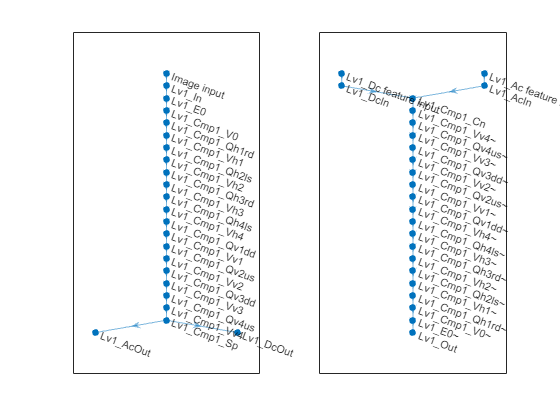

figure
subplot(1,2,1)
plot(lsunlgraphana)
subplot(1,2,2)
plot(lsunlgraphsyn)

## Linear autoencoder with LSUN

### Assemble analyzer

% Coefficient masking
nChsTotal = prod(stride);
coefMask = [ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)];
coefMask = [coefMask(1:2:end); coefMask(2:2:end)];

iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
%lsunlgraph = lsunlgraph.disconnectLayers([strLv 'AcOut'],[strLv 'AcIn']);
% For AC
lsunlgraphana = lsunlgraphana.replaceLayer([strLv 'AcOut'],...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
%lsunlgraph = lsunlgraph.connectLayers([strLv 'AcMask'],[strLv 'AcIn']);

lsunlgraphana = lsunlgraphana.addLayers(...
      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']));
lsunlgraphana = lsunlgraphana.connectLayers(...
    [strLv 'AcMask' ], [strLv strCmp 'Cn/ac']);
lsunlgraphana = lsunlgraphana.connectLayers(...
    [strLv 'DcOut' ], [strLv strCmp 'Cn/dc']);

% Outputlayer
lsunlgraphana = lsunlgraphana.addLayers(...
    regressionLayer('Name',[strLv strCmp 'Out']));
lsunlgraphana = lsunlgraphana.connectLayers(...
    [strLv strCmp 'Cn'],[strLv strCmp 'Out']);

figure
plot(lsunlgraphana)
title('Analysis LSUN')
lsunnetana = assembleNetwork(lsunlgraphana);

### Synthesizer construction

% TODO

## TODO

% TODO: Define the LSUN analyzer and synthesizer
analyzer_ = @(x) reshape(x,1,[]);
synthesizer_ = @(x) x;

### Project X and Y onto the LSUN feature space

% Project X and Y onto the LSUN feature space
Xlsun = zeros(szy*szx,nFrames-1,'like',vtpad);
Ylsun = zeros(szy*szx,nFrames-1,'like',vtpad);
for iFrame = 1:nFrames-1
    Xlsun(:,iFrame) = analyzer_(vtpad(:,:,iFrame)); 
    Ylsun(:,iFrame) = analyzer_(vtpad(:,:,iFrame+1)); 
end

### Apply piDMD

[piA2, piVals2] = piDMD(Xlsun,Ylsun,'orthogonal'); 
piAlsun = @(x) synthesizer_(piA2(analyzer_(x)));

## Plot some results

FS = 'FontSize'; IN = 'Interpreter'; LT = 'Latex'; MS = 'MarkerSize'; LW = 'LineWidth';
%
figure
clf
plot(exp(1i*linspace(0,2*pi)),'--','Color',[1 1 1]*.5,LW,2)
hold on
p2 = plot((exVals)+1i*eps,'r^',LW,2,MS,10);
p3 = plot((piVals1)+1i*eps,'bx',LW,2,MS,10);

grid on; axis equal; hold off
axis(1.3*[-1,1,-1,1])

legend([p2,p3],{'exact DMD','piDMD'},FS,15,IN,LT)
title('Spectrum of linear operator',FS,20,IN,LT)


## Local functions

### Definition of Drawing Function

function him = mycylinderplot_(him,x,clims)
if isempty(him)
    figure
    him = imagesc(x,clims);
    axis equal
    axis tight
    ax = gca;
    ax.XTick = [];
    ax.YTick = [];
    cmap = zeros(256,3);
    cmap(128:255,1) = 1;
    cmap(1:127,3) = 1;
    hsv = rgb2hsv(permute(cmap,[1 3 2]));
    hsv(:,2) = [254:-2:0 1:2:255].'/255;
    cmap = ipermute(hsv2rgb(hsv),[1 3 2]); 
    colormap(cmap)
else
    him.CData = x;
end
end

### Definition of Drawing POD mode trajectories

%{
function mypodmodetraj(At,modes)
tiledlayout(length(modes),1);
for mode = modes
    ak = At(mode,:);
    %
    nexttile
    plot(ak)
    ax = gca;
    ax.XLim = [0 size(ak,2)];
    ylabel("mode " + mode)
    if mode == modes(end)
        xlabel("time");
    else
        ax.XTick = [];
    end
end
end
%}

### Gradients w.r.t. LSUN design parameters

function [gradients, loss] = modelGradients(dlnet, dlX)
% Forward data through the dlnetwork object.
dlY = forward(dlnet,dlX); % F(x)
% Compute loss.
Nx = size(dlX,4);
Ny = size(dlY,4);
loss = sum(dlX.^2,"all")/Nx-sum(dlY.^2,"all")/Ny;
% Compute gradients.
gradients = dlgradient(loss,dlnet.Learnables);
loss = double(gather(extractdata(loss)));
end

### MiniBatch function

function X = preprocessMiniBatch(XCell)
    % Extract image data from the cell array and concatenate over fourth
    % dimension to add a third singleton dimension, as the channel
    % dimension.
    X = cat(4,XCell{:});
end

### Information extractors

function nLevels = extractnumlevels(lsun)
import tansacnet.lsun.*

% Extraction of information
expidctlayer = '^Lv\d+_E0~?$';
nLevels = 0;
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expidctlayer,'once'))
        nLevels = nLevels + 1;
    end
end
end

function stride = extractstride(lsun)
import tansacnet.lsun.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        stride = layer.Stride;
    end
end
end

function ovlpFactor = extractovlpfactor(lsun)
import tansacnet.lsun.*

% Extraction of information
expanalyzerv = '^Lv\d+_Cmp\d+_Vv(\d)+$';
expanalyzerh = '^Lv\d+_Cmp\d+_Vh(\d)+$';
nLayers = height(lsun.Layers);
ovlph = 1;
ovlpv = 1;
for iLayer = 1:nLayers
    alayer = lsun.Layers(iLayer);
    alayerName = alayer.Name;
    if ~isempty(regexp(alayerName,expanalyzerv,'once'))
        ovlpv = ovlpv + 1;
    elseif ~isempty(regexp(alayerName,expanalyzerh,'once'))
        ovlph = ovlph + 1;
    end
end

ovlpFactor = [ovlpv ovlph];

end

function noDcLeakage = extractnodcleakage(lsun)
import tansacnet.lsun.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        noDcLeakage = layer.NoDcLeakage;
    end
end

end